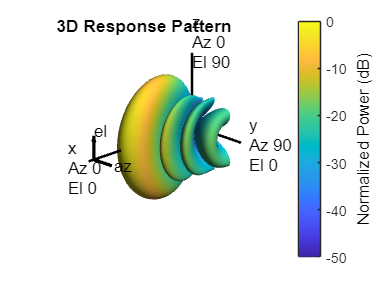

% Definerer parametere
c = 3e8; % Lyshastighet
f = 24.13e9; % Frekvens
lambda = c/f; % Bølgelengde
d = lambda/2; % Avstand mellom elementene

% Oppretter array
array = phased.URA('Size',[2 8],'ElementSpacing',[d d],'Element',phased.IsotropicAntennaElement('FrequencyRange',[14e9 34e9]));

% Oppretter strålingsdiagram
figure;
pattern(array,f,-90:90,-90:90,'Type','powerdb','CoordinateSystem','polar','Normalize',true);

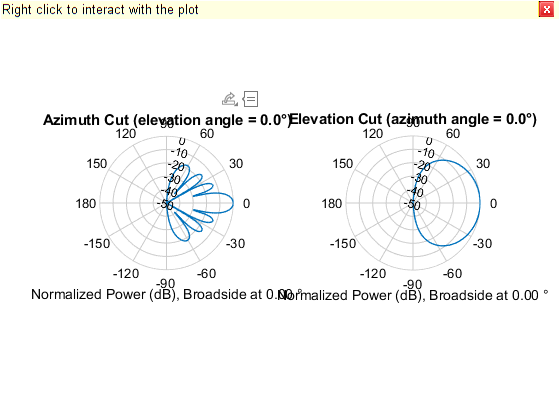


figure;
subplot(1,2,1);
pattern(array,f,-90:90,0,'Type','powerdb','CoordinateSystem','polar','Normalize',true);
title('Azimuth');
subplot(1,2,2);
pattern(array,f,0,-90:90,'Type','powerdb','CoordinateSystem','polar','Normalize',true);
title('Elevation');